# Flight Path Optimization

This script demonstrates the use of Optimization Toolbox™ to solve a simple pathfinding problem. 

We are given an airplane with a fixed airspeed and a vector field of wind in which to navigate. The objective is to find the path which minimizes the time taken to travel from the starting point to the finish point.

We can also find the optimal path when an initial wind field evolves to a second wind field. We navigate by recomputing the path at each time step to account for the time-varying wind field.

## Set parameters



clear;

global W_x
global W_y
global AirSpeed
global sizeX 
global sizeY
global method
global integrationFineness


AirSpeed = 500;
sizeX = 50;
sizeY = 25;
numWayPoints = 5;
randomSeed = 50;
rng(randomSeed);
method ="pchip" ; % Interpolation method
integrationFineness = 101;

## Fixed Wind Field

### Generate a random wind field







pathAxes = axes;
W_x = makeWindFun(sizeX,sizeY);
W_y = makeWindFun(sizeX,sizeY);
[Xgrid,Ygrid] = meshgrid(0:sizeX,0:sizeY);
hq = quiver(pathAxes,Xgrid,Ygrid,W_x,W_y,"k");

hold(pathAxes,"on");

pathAxes.XLabel.String = "Units = 100 [km]";
pathAxes.XLim = [0 sizeX];
pathAxes.YLim = [0 sizeY];
pathAxes.DataAspectRatio = [1 1 1];

plot(pathAxes,[0 sizeX],[sizeY sizeY]/2,"k.","MarkerSize",16)

Add some color to make it more visible by generating an image from the favorability of the wind to use as the background.

L = (sqrt((Xgrid-sizeX).^2 + (Ygrid-sizeY/2).^2));
Favorability = ((sizeX-Xgrid).*W_x +  (sizeY/2-Ygrid).*W_y)./L;
Favorability(~isfinite(Favorability)) = 0;

h_im = imagesc(pathAxes,Favorability);
set(h_im,"Xdata",[0 sizeX],"Ydata",[0 sizeY]);
uistack(h_im,"bottom");

Change the colormap.

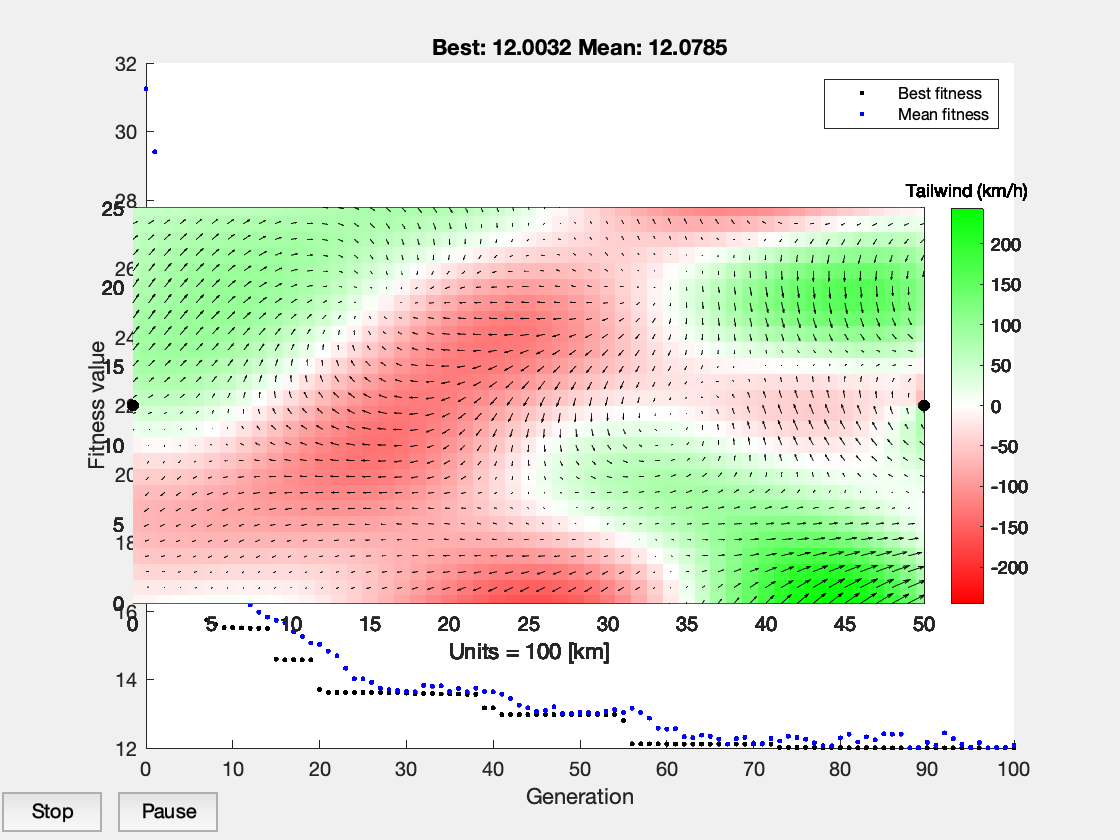

colormap(pathAxes,interp1([0,1,2],[1 0 0; 1 1 1; 0 1 0],0:0.01:2));
caxis(pathAxes,max(abs(Favorability(:)))*[-1 1]);

h_colorbar = colorbar(pathAxes);
title(h_colorbar,"Tailwind (km/h)")

### Generate waypoints in a straight line

Generate the points and plot.

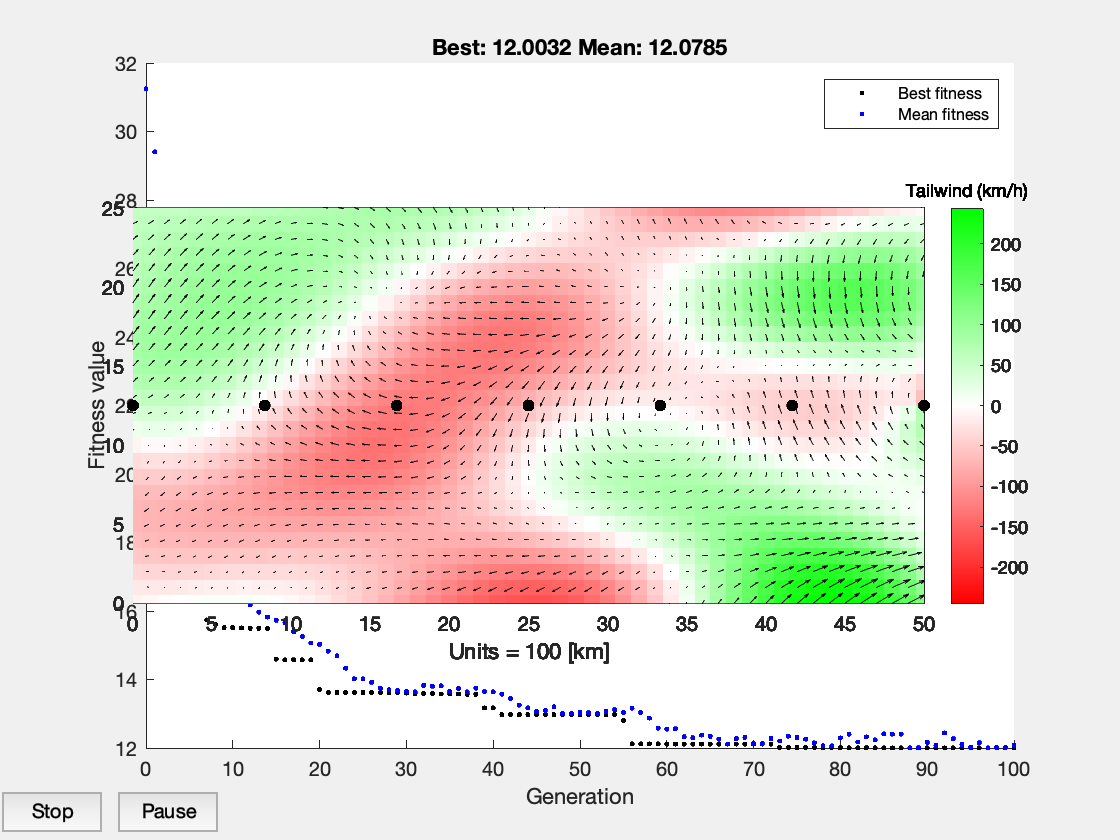

xWayPoints = linspace(0,sizeX,numWayPoints+2)';
yWayPoints = sizeY/2 * ones(numWayPoints+2,1);

h_wp = plot(pathAxes,xWayPoints,yWayPoints,"Color","k","LineStyle","none","Marker",".","MarkerSize",16);

Generate a continuous path from the points

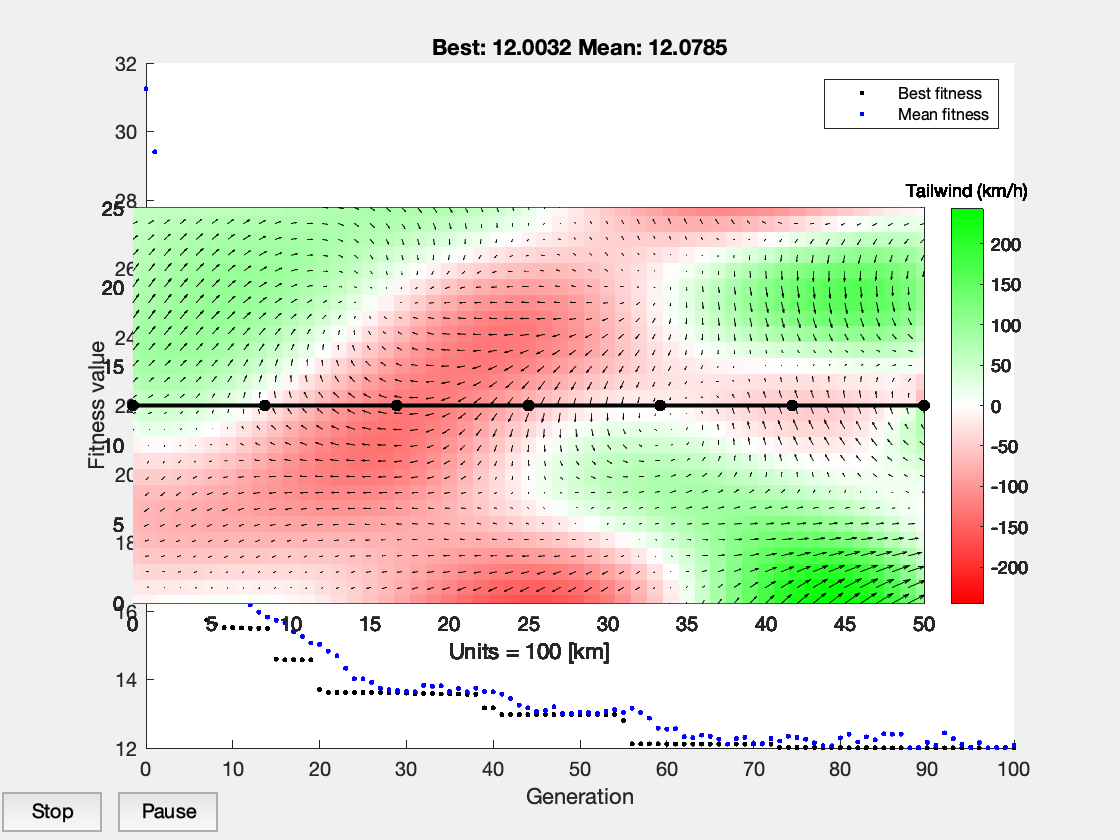

pathPoints = waypointsToPath([xWayPoints,yWayPoints],method,sizeX,sizeY,integrationFineness);
h_path = plot(pathAxes,pathPoints(:,1),pathPoints(:,2),"k","LineWidth",2);

Calculate the time taken

straightLineTime = getTimeFromPath(pathPoints,W_x,W_y,AirSpeed);

dP =     0.5000         0
    0.5000         0
    0.5000         0
    0.5000         0
    0.5000         0
    0.5000         0
    0.5000         0
    0.5000         0
    0.5000         0
    0.5000         0


   47.2233   24.1838
   49.0942   25.7772
   50.9651   27.3706
   51.2331   29.8863
   51.5010   32.4020
   50.1160   35.7146
   48.7309   39.0272
   45.7158   42.9453
   42.7007   46.8634
   38.1510   51.1386
   33.6013   55.4137
   27.6808   59.7531
   21.7603   64.0925
   14.6939   68.1746
    7.6275   72.2567
   -0.3089   75.7496
   -8.2453   79.2426
  -16.7378   81.8232
  -25.2302   84.4038
  -33.9413   85.7776
  -42.6523   87.1513
  -51.2364   87.0706
  -59.8205   86.9898
  -67.9400   85.2707
  -76.0596   83.5515
  -83.4007   80.0871
  -90.7417   76.6228
  -97.0280   71.3930
 -103.3143   66.1633
 -108.3198   59.2400
 -113.3253   52.3166
 -116.8840   43.8635
 -120.4426   35.4103
 -122.4554   25.6784
 -124.4681   15.9465
 -124.9062    5.2645
 -125.3444   -5.4174
 -124.2502  -16.6568
 -123.1559  -27.8963
 -120.6387  -39.2549
 -118.1215  -50.6135
 -114.3516  -61.6271
 -110.5818  -72.6408
 -105.7812  -82.8421
 -100.9806  -93.0435
  -95.4106 -101.9846
  -89.8407 -110.9257
  -83.7891 -1


% Display in Hours/Minutes
fprintf("Straight Line Travel Time: %d hours, %.1f minutes\n",floor(straightLineTime),rem(straightLineTime,1)*60);

Straight Line Travel Time: 10 hours, 58.8 minutes


### Generate randomly chosen waypoints

xWayPoints = linspace(0,sizeX,numWayPoints+2)' .* (1+0.05*randn(size(xWayPoints)));
yWayPoints = sizeY/2 + (0.1*sizeY*randn(numWayPoints+2,1));
xWayPoints([1 end]) = [0 sizeX];
yWayPoints([1 end]) = sizeY/2;

Plot them

delete([h_wp h_path]);
h_wp = plot(pathAxes,xWayPoints,yWayPoints,"Color","k","LineStyle","none","Marker",".","MarkerSize",16);

Generate a continuous path from the waypoints

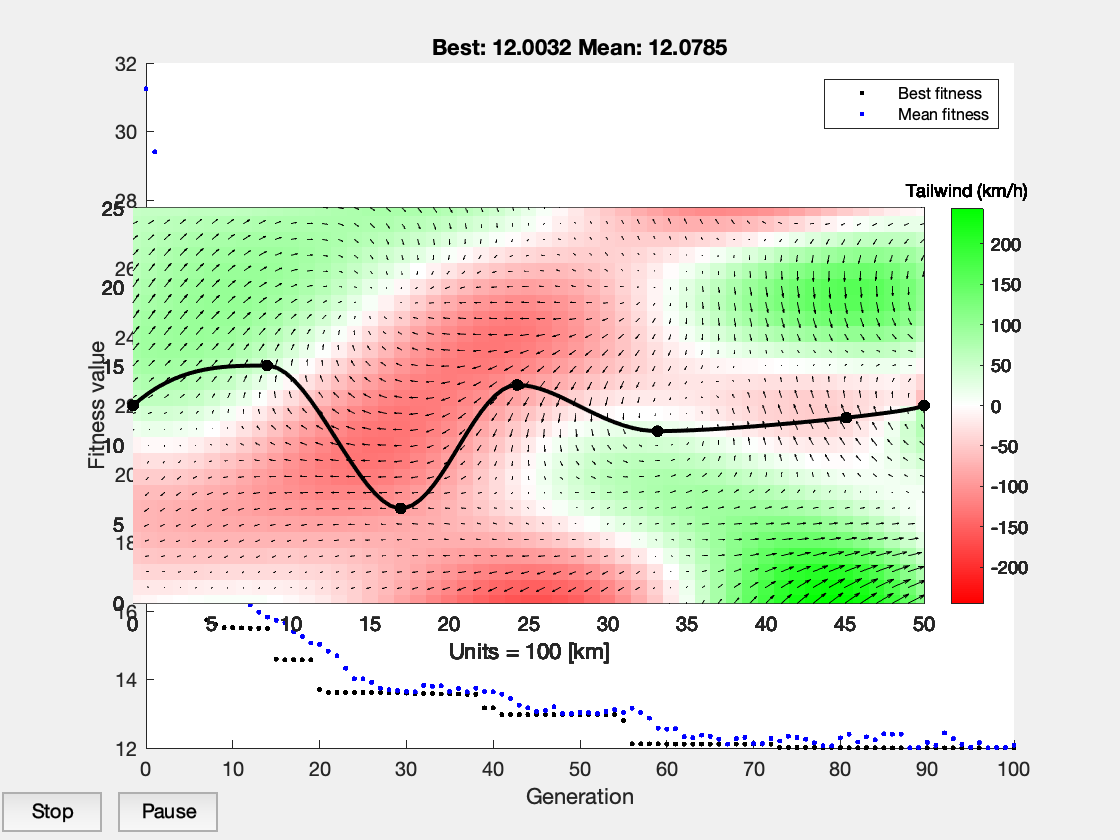

pathPoints = waypointsToPath([xWayPoints,yWayPoints],method,sizeX,sizeY,integrationFineness);
h_path = plot(pathAxes,pathPoints(:,1),pathPoints(:,2),"k","LineWidth",2);

Calculate the time taken

lineTime = getTimeFromPath(pathPoints,W_x,W_y,AirSpeed);

dP =     0.5092    0.4274
    0.5091    0.3762
    0.5090    0.3282
    0.5089    0.2836
    0.5088    0.2421
    0.5087    0.2040
    0.5086    0.1691
    0.5085    0.1375
    0.5084    0.1092
    0.5083    0.0841


   47.2233   24.1838
   57.6395   37.2287
   65.8828   48.3095
   71.7334   58.2764
   76.8799   66.5371
   79.5882   73.4993
   81.5632   78.9953
   82.0889   83.6979
   82.2025   87.4232
   80.9494   90.5423
   79.2408   93.0033
   76.2341   95.0387
   72.7431   96.6776
   68.0583   98.0142
   62.8718   99.0764
   56.6805   99.8877
   50.1331  100.5665
   42.5908  100.9647
   31.2417  100.9298
   14.9740  100.4982
   -5.3788  100.2097
  -29.3730   96.5659
  -55.2892   90.4609
  -80.8736   79.5377
 -102.7639   64.3450
 -119.1749   47.0821
 -128.6337   29.9018
 -131.3233   15.2048
 -127.3788    5.0707
 -120.1035   -0.3531
 -111.9593   -2.5261
 -104.2566   -1.9295
  -98.3977   -0.4985
  -94.5891    0.9698
  -92.5413    1.5295
  -91.4636    0.4918
  -90.7308   -2.6187
  -89.3365   -8.1573
  -88.4022  -17.1869
  -86.4701  -29.3374
  -85.4446  -43.8180
  -84.7894  -58.7724
  -85.1953  -73.7423
  -87.3054  -85.4168
  -90.4273  -92.7582
  -94.7336  -98.4352
  -98.8782  -98.9498
 -102.8308 -1

fprintf("Travel Time: %d hours, %.1f minutes\n",floor(lineTime),rem(lineTime,1)*60);

Travel Time: 12 hours, 48.8 minutes


### Find an optimal path using `fmincon`

Find the optimal waypoints. Define the objective function to minimize the time take on the path interpolated from the waypoints. 

objectiveFun = @(P) getTimeFromPath(P,W_x,W_y,AirSpeed,sizeX,sizeY,method,integrationFineness);

Set optimization options

opts = optimoptions("fmincon");
opts.Display = "iter";
opts.Algorithm = "sqp";
opts.MaxFunctionEvaluations = numWayPoints*500;

Use the straight-line waypoints for the initial point

xWayPoints = linspace(0,sizeX,numWayPoints+2)';
yWayPoints = sizeY/2 * ones(numWayPoints+2,1);
ipt = [xWayPoints(2:end-1)'; yWayPoints(2:end-1)'];
ipt = ipt(:);

Specify lower and upper bounds on the waypoints.

lb = zeros(5,1);
ub = sizeX*ones(1,numWayPoints);

Do the optimization

options = optimoptions('ga');
options = optimoptions(options,'MaxGenerations', 100);
options = optimoptions(options,'CreationFcn', @gacreationuniform);
options = optimoptions(options,'CrossoverFcn', @crossoverscattered);
options = optimoptions(options,'MutationFcn', {  @mutationuniform [] });
options = optimoptions(options,'Display', 'iter');
options = optimoptions(options,'MaxStallGenerations', 40);
options = optimoptions(options, 'PlotFcn', @gaplotbestf);
options = optimoptions(options,'PopulationSize', 100);

nvars = length(ipt)/2

nvars = 5

MaxGenerations_Data = 200;

[optimalWayPoints,fval,exitflag,output,population,score] = RMOGA(nvars,lb,ub,MaxGenerations_Data);

Matrix dimensions must agree.

Error in getTimeFromPath (line 20)
V_add = (sum(V_wind.*dP,2))./sqrt(sum(dP.^2,2));

Error in objective_functionRunMOGA_FFP (line 27)
F1 = getTimeFromPath(Reshaped,W_x,W_y,AirSpeed,sizeX,sizeY,method,integrationFineness);

Error in 



%[optimalWayPoints, fval] = ga(objectiveFun, length(ipt), [], [], [], [], lb, ub, [], options)

optimalWayPoints = [0 sizeY/2; reshape(optimalWayPoints,2,[])'; sizeX sizeY/2]

### Plot the optimal solution

delete([h_wp h_path]);

% for i = 1:size(optimalWayPoints, 1)
    xWayPoints = optimalWayPoints(:,1);
    yWayPoints = optimalWayPoints(:,2);
    h_wp = plot(pathAxes,xWayPoints,yWayPoints,"Color","k","LineStyle","none","Marker",".","MarkerSize",16);
    pathPoints = waypointsToPath([xWayPoints,yWayPoints],method,sizeX,sizeY,integrationFineness);
    %h_path = plot(pathAxes,pathPoints(:,1),pathPoints(:,2),"k","LineWidth",2);
% end 




lineTime = getTimeFromPath(pathPoints,W_x,W_y,AirSpeed);
fprintf("Optimal Travel Time: %d hours, %.1f minutes\n",floor(lineTime),rem(lineTime,1)*60);

## Time-Varying Wind Field

### Generate two random wind fields

The wind field at each time step is a convex combination of the two windfields, changing from the initial to the final wind field.

W_x0 = makeWindFun(sizeX,sizeY);
W_y0 = makeWindFun(sizeX,sizeY);
W_x1 = makeWindFun(sizeX,sizeY);
W_y1 = makeWindFun(sizeX,sizeY);

try
    delete([hq h_wp h_path])
catch
end

[Xgrid,Ygrid] = meshgrid(0:sizeX,0:sizeY);
hq = quiver(pathAxes,Xgrid,Ygrid,W_x0,W_y0,"k");

Add some color to make it more visible

L = (sqrt((Xgrid-sizeX).^2 + (Ygrid-sizeY/2).^2));
Favorability = ((sizeX-Xgrid).*W_x0 +  (sizeY/2-Ygrid).*W_y0)./L;
Favorability(~isfinite(Favorability)) = 0;
Favorability0 = Favorability; %Record this so we can reuse it later

Favorability = ((sizeX-Xgrid).*W_x1 +  (sizeY/2-Ygrid).*W_y1)./L;
Favorability(~isfinite(Favorability)) = 0;
Favorability1 = Favorability; %Record this so we can reuse it later

hold(pathAxes,"on");
h_im = imagesc(pathAxes,Favorability0); % This will be the background for the vector field
set(h_im,"Xdata",[0 sizeX],"Ydata",[0 sizeY]);
uistack(h_im,"bottom");

title(pathAxes,"Time-Varying Path Optimization")

### Re-calculate the solution at each time step

In this optimization, we will assume that the x location of each waypoint is equally spaced, and we only optimize over the y values.

opts = optimoptions("fmincon");
opts.Display = "off";
opts.Algorithm = "sqp";

Initial point for first time step

X_points = linspace(0,sizeX,numWayPoints+2)';
x_opt = sizeY/2*ones(numWayPoints,1);
ystart = sizeY/2;

timeStep = 1/40;
K_PointListX = cell(40);
K_PointListY = cell(40);
K_k = cell(40);
kctr = 1;

for time = 0: timeStep : 1-timeStep
    fprintf("%02.f%% Percent Complete\n",kctr*timeStep*100);
    W_x = (1-time)*W_x0 + time*W_x1;
    W_y = (1-time)*W_y0 + time*W_y1;
    
    % Make initial point based on the previous solution
    xstart = sizeX*time;
    points = [X_points [ystart; x_opt; sizeY/2]];
    X_points_old = X_points;
    X_points = linspace(xstart,sizeX,numWayPoints+2)';
    xy0 = interp1(X_points_old,points(:,2),X_points(2:end-1),method,"extrap");
    ystart = interp1(X_points_old,points(:,2),xstart,method,"extrap");
    
    lb = zeros(size(xy0(:)));
    ub = sizeY*ones(numWayPoints,1);
    
    % Define and solve the new optimization problem
    objectiveFun = @(P) ...
        calculateTimeIntermediate(P,W_x,W_y,xstart,ystart,AirSpeed,sizeX,sizeY,method,integrationFineness);
    x_opt = fmincon(objectiveFun,xy0(:),[],[],[],[],lb,ub,[],opts);
       
    points = [X_points [ystart; x_opt; sizeY/2]];
    PointList = waypointsToPath(points,method,sizeX,sizeY,integrationFineness);
    
    K_PointListX{kctr} = PointList(:,1);
    K_PointListY{kctr} = PointList(:,2);
    K_k{kctr} = time;
    kctr = kctr+1;
    if time == 0
        plot(pathAxes,PointList(:,1),PointList(:,2),"b","LineWidth",2);
        drawnow;
    end
end

### Plot the results

% pause;

for kk = 1:kctr-1
    time = K_k{kk};
    W_x = (1-time)*W_x0 + time*W_x1;
    W_y = (1-time)*W_y0 + time*W_y1;
    
    set(hq,"Udata",W_x,"Vdata",W_y);
    try 
        delete(hthis)
    catch
    end
    hthis = plot(pathAxes,K_PointListX{kk},K_PointListY{kk},"k","LineWidth",2);
    if kk == 1
        plot(pathAxes,K_PointListX{kk},K_PointListY{kk},"b","LineWidth",2);
        pause(1);
    end
    
    %Update the background image, as well as the path line
    plot(pathAxes,K_PointListX{kk}(1),K_PointListY{kk}(1),"k.","MarkerSize",16);
    Favorability = ((sizeX-Xgrid).*W_x +  (sizeY/2-Ygrid).*W_y)./L;
    Favorability(~isfinite(Favorability)) = 0;
    set(h_im,"Cdata",Favorability);
    
    drawnow
end

## Helper Functions

### makeWindFun

function iWind = makeWindFun(SZX,SZY)
% This is just a helper function to make a random scalar function. This is
% called twice to generate a random wind field.

windFineness = 0.1;
if ~exist("SZX","var")
    SZX = 50;
    SZY = 50;
end

N = 50; % Various parameters used in generating a random "smooth" matrix
NL = 40;
NP = 500;
rx = randn(NL,N);
rx = interpft(rx,NP);
ry = randn(NL,N);
ry = interpft(ry,NP);
I = (rx*ry');

[xgi,ygi] = meshgrid(linspace(1,2 + 498*windFineness,SZX+1),linspace(1,2 + 498*windFineness,SZY+1));
iWind = 10*interp2(1:500,1:500,I,xgi,ygi);
end

### waypointsToPath

function pathPoints = waypointsToPath(p,method,sizeX,sizeY,fineness)
% Interpolate the curve based on the discrete waypoints to generate a
% continuous path.

nP = size(p,1);
pathPoints = [interp1(1:nP,p(:,1),linspace(1,nP,fineness)',method,"extrap") ...
    interp1(1:nP,p(:,2),linspace(1,nP,fineness)',method,"extrap")];

% Do not leave the box
pathPoints(:,1) = min(pathPoints(:,1),sizeX);
pathPoints(:,1) = max(pathPoints(:,1),0);
pathPoints(:,2) = min(pathPoints(:,2),sizeY);
pathPoints(:,2) = max(pathPoints(:,2),0);
end

### getTimeFromPath

function travelTime = getTimeFromPath(pathPoints,W_x,W_y,AirSpeed,sizeX,sizeY,method,integrationFineness)
% This is the main function that actually calculates the line integral
% along the path. This is the objective function for the optimizer.

% If we are called from the optimization routine (caller = "optimizer")
% then we need to interpolate the fine path from the input control points.
if isvector(pathPoints)
    pathPoints = [0 sizeY/2; reshape(pathPoints,2,[])'; sizeX sizeY/2];
    pathPoints = waypointsToPath(pathPoints,method,sizeX,sizeY,integrationFineness);
end

dP = diff(pathPoints)
%disp(dP)

% Interpolate the wind vector field at all the points in pathPoints.
V_wind = [interp2(W_x,pathPoints(1:end-1,1)+1,pathPoints(1:end-1,2)+1,"linear") ...
    interp2(W_y,pathPoints(1:end-1,1)+1,pathPoints(1:end-1,2)+1,"linear")];
disp(V_wind)

% Dot product the wind (V_wind) with the direction vector (dP) to get
% the tailwind/headwind contribution
V_add = (sum(V_wind.*dP,2))./sqrt(sum(dP.^2,2));
dx = sqrt(sum(dP.^2,2))*100; %dx is the length of each subinterval in pathPoints
dt = dx./(AirSpeed+V_add);  %dT = dP/dV
travelTime = sum(dt);
end

### calculateTimeIntermediate

function totalTime = calculateTimeIntermediate(x,W_x,W_y,x0,y0,AirSpeed,sizeX,sizeY,method,integrationFineness)
% This calculates the time starting from a specified start point (x0,y0)
% It is used in the time-dependent version of this optimization problem.

L = numel(x);
X_points = linspace(x0,sizeX,L+2)';

points = [X_points [y0; x; sizeY/2]];

PointList = [interp1(X_points,points(:,1),linspace(x0,sizeX,integrationFineness)',method,"extrap") ...
    interp1(X_points,points(:,2),linspace(x0,sizeX,integrationFineness)',method,"extrap")];

PointList(PointList < 0) = 0;
PointList(:,1) = min(PointList(:,1),sizeX);
PointList(:,2) = min(PointList(:,2),sizeY);

dP = diff(PointList);

V_wind = [interp2(W_x,PointList(1:end-1,1)+1,PointList(1:end-1,2)+1,"linear")...
    interp2(W_y,PointList(1:end-1,1)+1,PointList(1:end-1,2)+1,"linear")];

% Dot product the wind (V_wind) with the direction vector (dP)
V_add = (sum(V_wind.*dP,2))./sqrt(sum(dP.^2,2));

dx = sqrt(sum(dP.^2,2)); % dx is the length of each subinterval in plist
dT = dx./(AirSpeed+V_add);  % dT = dP/dV
totalTime = 100*sum(dT);
end

Copyright 2012-2019 The MathWorks, Inc. 